# GCPhat

Vamos a probar el algoritmo para detectar el ángulo de una fuente de audio, en base a las señales captadas por dos microfonos distintos. La distancia entre dichos microfonos fue 18cm.

En este audio la fuente se encocntraba a 60 grados respecto a la normal y a 90 -60 =30 grados respecto a la recta que une los microfonos.

*Los audios me los pasaron amigos para hacer pruebas.

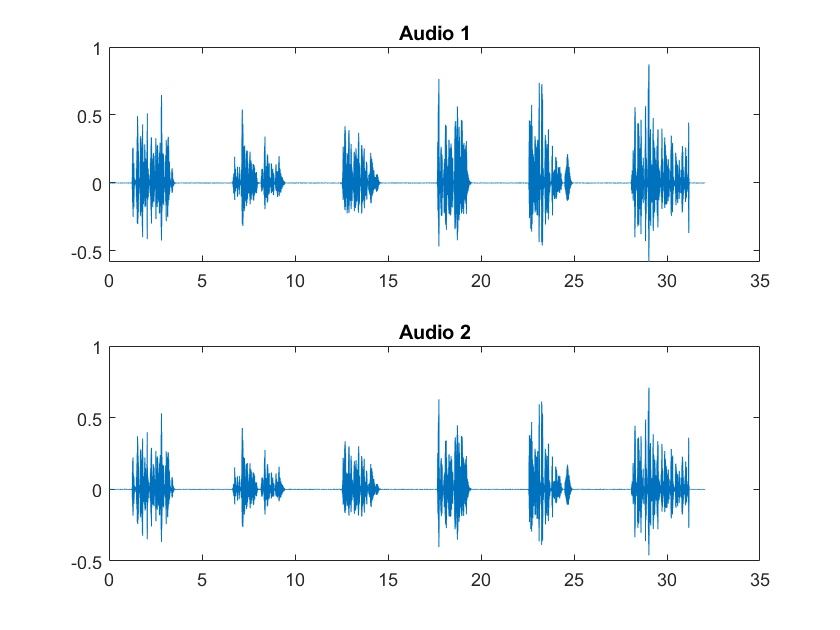

%Abrimos los audios
[audio1, Fs1] = audioread("wav_mic1.wav");
[audio2, Fs2] = audioread("wav_mic2.wav");
tArray = (1/Fs1)*(1:length(audio1));

figure()
subplot(2,1,1) 
plot(tArray, audio1)
title("Audio 1")
subplot(2,1,2)
plot(tArray, audio2)
title("Audio 2")

distanceMics = 0.18;
%Inicialamos el detector de dirección
sourceDetector = GCPhatDirectionDetector(tArray, audio1, audio2, distanceMics);
%Obtenemos la dirección
[dir, timeDelay, tArrCorr, correlation] = sourceDetector.getDirection();

    0.3205

here


disp("La dirección es "+string(dir));

La dirección es 29.1462


disp("theta = "+string(90 - dir))

theta = 60.8538


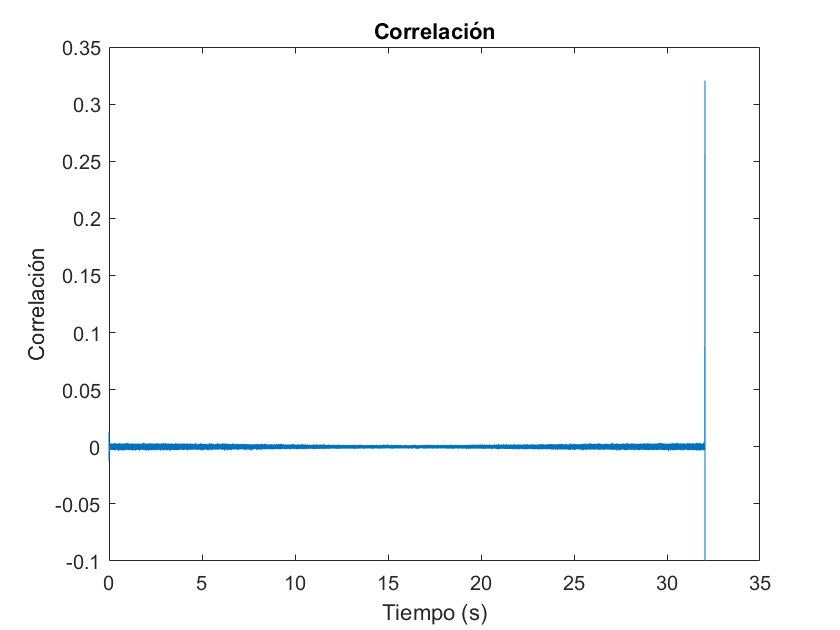

figure()
plot(tArrCorr, correlation)
title("Correlación")
xlabel("Tiempo (s)")
ylabel("Correlación")

### Gráfico de correlación contra ángulo

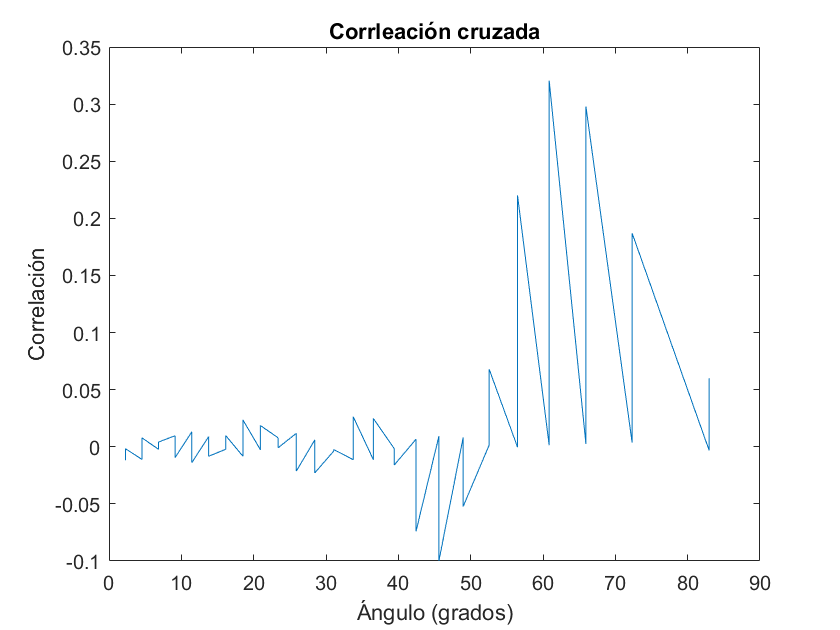

speedOfSound = sourceDetector.soundSpeed;
maxSearchTime = distanceMics/speedOfSound;
angles = [];
correlationValues = [];
maxIndex = floor(Fs1*maxSearchTime);

for i = 1:maxIndex
    time = tArrCorr(i);
    angles = [angles, pi/2 - acos(speedOfSound*time/distanceMics)];
    correlationValues = [correlationValues, correlation(i)];
end

for i = length(tArrCorr) - maxIndex + 1:length(tArrCorr)
    index = length(tArrCorr) - i + 1;
    time = tArrCorr(index);
    angles = [angles, pi/2 - acos(speedOfSound*time/distanceMics)];
    correlationValues = [correlationValues, correlation(i)];
    
end


[sortedAngles,indexes] = sort(abs(angles));
correlationValues = correlationValues(indexes);

sortedAngles = sortedAngles*(180/pi);
figure()
plot(sortedAngles, correlationValues)
title("Corrleación cruzada")
xlabel("Ángulo (grados)")
ylabel("Correlación")